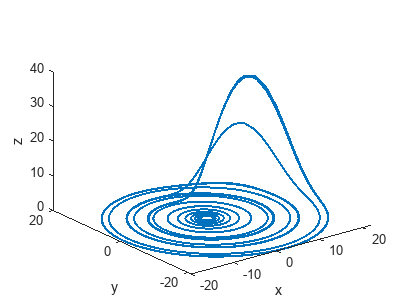


clc;
close all;
clear; 

% Rössler attractor parameters
a = 0.1;
b = 0.1;
c = 14;

% Rössler attractor equations
dxdt = @(t,x) [-x(2)-x(3); x(1)+a*x(2); b+x(3)*(x(1)-c)];

% Initial conditions
x0 = [0; 1; 0];

% Time interval
tspan = [0 100];

% Solve the ODE using MATLAB's ode45 solver
[t,x] = ode45(dxdt, tspan, x0);

% Plot the Rössler attractor
plot3(x(:,1), x(:,2), x(:,3), 'LineWidth', 1.5);
xlabel('x');
ylabel('y');
zlabel('z');